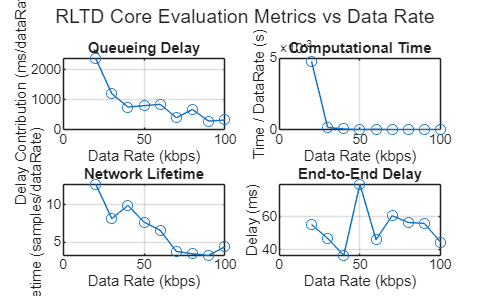

% RLTD Protocol Simulation for WBASN (Updated with Throughput, Routing Overhead, and Jitter)
% Key characteristics:
%   - No direct source-to-sink transmission. All data must use relay nodes.
%   - Routing decisions consider link quality, temperature, delay, hop count, reliability, and malicious nodes.
%   - Metrics include: Queueing Delay, Computational Time, Network Lifetime,
%     End-to-End Delay, Throughput, Routing Overhead, Jitter, and Per-Source Energy.
%
% This version also saves all metric CSV files to:
%   C:\Users\saidu\Documents\MATLAB

clc; clear;

%% Output Directory for CSV results
outDir = 'C:\Users\saidu\Documents\MATLAB';
if ~exist(outDir,'dir')
    mkdir(outDir);
end

%% Network Parameters
areaSize = 200;                 % cm (2m x 2m)
numRelays = 12;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;
range = 50;                     % cm communication range
initialEnergy = 50;             % J initial energy per node
energyThreshold = 0.2 * initialEnergy; % node considered "dead" below this
tempThreshold = 37 + 5;         % 42 C threshold
tempBase = 36 + rand(numNodes,1)*7; % assign base temperature per node in [36,43)
reliabilityThreshold = 0.6;
packetSize = 1500;              % bytes per packet
dataRates = 20:10:100;          % kbps sweep
simTime = 1000;                 % seconds (reference; not directly iterated)
queueDelayBase = 5;             % ms base queuing delay per hop
queueVar = 10;                  % ms random queuing variation per hop

%% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);

%% Import CSV Data
sensorData = readmatrix('DATA.csv');
numSamples = size(sensorData,1);

%% Metrics Collection for Different Data Rates
% metrics columns:
% 1 QueueingDelay
% 2 ComputationalTime
% 3 NetworkLifetime
% 4 EndToEndDelay
% 5 Throughput
% 6 RoutingOverhead
% 7 Jitter
metrics = zeros(length(dataRates), 7);

% Energy consumed per source node across dataRates
energyPerSource = zeros(length(dataRates), numSources);

% We will also store a transmission log for the LAST data rate iteration
% (dimension: time samples x number of sources)
transmissionLog = strings(numSamples, numSources);

%% MAIN LOOP: iterate over each data rate
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);

    % Reset dynamic state for this data rate
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);

    % RLTD cost initialized as Inf (unusable) until validated
    RLTD_Cost = inf(numNodes, 1);

    % Per-run metrics accumulation
    totalQueueDelay = 0;                 % for Queueing Delay metric
    networkLifetime = 0;                 % first time a node "dies"
    totalE2EDelay = zeros(numSamples, 1);% per-sample average E2E delay

    % Additional metrics
    allPacketDelays = [];                % ms delay for each delivered packet
    deliveredPackets = 0;                % total successfully forwarded packets
    relayPackets = 0;                    % packets that used a relay (in RLTD this will track forwarding activity)

    % Queue fluctuation profile over time samples
    queueFluctuation = 1 + 0.3 * sin(1:numSamples);

    % -----------------------------
    % RLTD COST COMPUTATION PHASE
    % -----------------------------
    % Start computation timer
    tStart = tic;

    % Link quality and reliability metrics for nodes
    SNR = 10 + rand(numNodes, 1) * 20;            % SNR per node (arbitrary model)
    SINR = SNR - (1 + rand(numNodes, 1) * 5);     % SINR slightly worse than SNR
    interferenceRatio = SINR ./ SNR;              % interference ratio
    Delay = rand(numNodes,1) * 100;               % ms per-node delay baseline
    LQI = interferenceRatio + Delay;              % link quality indicator
    reliability = rand(numNodes, 1);              % node reliability score [0,1]
    HopCount = randi([1, 4], numNodes, 1);        % hop count estimate (1-4 pseudo)
    numMalicious = randi([1, 3]);                 % randomly mark some malicious relays
    maliciousNodes = randperm(numRelays, numMalicious);

    % Compute RLTD cost for each node (potential forwarder):
    % Only nodes that satisfy constraints (energy, temp, reliability, non-malicious) are valid.
    for i = 1:numNodes-1
        if energy(i) >= energyThreshold && ...
           tempBase(i) <= tempThreshold && ...
           reliability(i) >= reliabilityThreshold && ...
           ~ismember(i, maliciousNodes)

            RLTD_Cost(i) = 0.4 * LQI(i) + ...
                           0.2 * tempBase(i) + ...
                           0.2 * Delay(i) + ...
                           0.2 * HopCount(i);
        end
    end

    % Stop timer and normalize computation time metric by data rate
    tComp = toc(tStart) / dataRate;

    % ----------------------------------
    % ROUTING / TRANSMISSION PHASE
    % ----------------------------------
    for t = 1:numSamples
        roundE2EDelay = 0;
        validCount = 0;

        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID)
                continue;
            end

            % RLTD does NOT allow direct source->sink transmission.
            % All packets must forward through relay nodes.

            % For consistency with logging, we assign "00" to indicate normal routing format.
            % (Critical/normal classification not explicitly modeled here.)
            transmissionLog(t, s) = "00";

            % Determine candidate relay nodes for this source
            dists = vecnorm(positions - positions(srcID,:), 2, 2);

            eligible = find( ...
                dists <= range & ...                % relay must be within range
                RLTD_Cost < inf & ...               % relay must have finite / valid RLTD cost
                roles == "Relay" & ...              % must be a relay node
                ~nodeDead & ...                     % relay must still be alive
                tempBase <= tempThreshold);         % relay must not be overheated

            if isempty(eligible)
                % no relay path available -> packet not delivered
                continue;
            end

            % Extract RLTD cost for these eligible relays
            eligibleCosts = RLTD_Cost(min(eligible, numel(RLTD_Cost)));
            if length(eligibleCosts) ~= length(eligible)
                % defensive check for indexing mismatch (should not normally happen)
                continue;
            end

            % Pick best relay with minimum RLTD cost
            [~, bestIdx] = min(eligibleCosts);
            nextHop = eligible(bestIdx);

            % Model per-packet queuing delay on this hop
            qDelay = (queueDelayBase + rand() * queueVar) * queueFluctuation(t); % ms

            % Total per-packet end-to-end delay contribution for this transmission
            % We consider hop queuing + relay delay component
            perPacketDelay = qDelay + Delay(nextHop); % ms

            % Accumulate delay for this round
            roundE2EDelay = roundE2EDelay + perPacketDelay;

            % Accumulate global queueing delay
            totalQueueDelay = totalQueueDelay + qDelay;

            % Energy consumption: both source and relay pay cost
            energy([srcID, nextHop]) = energy([srcID, nextHop]) - 0.05;

            % Track packet success (for throughput etc.)
            deliveredPackets = deliveredPackets + 1;
            relayPackets = relayPackets + 1; % RLTD always uses relay forwarding
            allPacketDelays(end+1,1) = perPacketDelay; %#ok<SAGROW>

            % Death detection and lifetime logging
            for n = [srcID, nextHop]
                if energy(n) < energyThreshold && ~nodeDead(n)
                    nodeDead(n) = true;
                    if networkLifetime == 0
                        % record approximate time of first node death
                        networkLifetime = t * (0.9 + 0.2 * rand());
                    end
                end
            end

            % Count how many valid transmissions occurred in this time sample
            validCount = validCount + 1;
        end % for each source s

        % Average end-to-end delay for this "round" (time index t)
        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end % for each time sample t

    % ----------------------------------
    % METRIC CALCULATION (per dataRate)
    % ----------------------------------

    % Queueing Delay metric (scaled by data rate)
    queueingDelayMetric = totalQueueDelay / dataRate;

    % Computational Time metric
    compTimeMetric = tComp;

    % Network Lifetime metric
    lifetimeMetric = networkLifetime / dataRate;

    % End-to-End Delay metric
    avgValidE2EDelay = mean(totalE2EDelay(~isnan(totalE2EDelay)));

    % Throughput (Mbps)
    % bits delivered per simulated second (numSamples ~ seconds)
    bitsDelivered = deliveredPackets * packetSize * 8;
    durationSeconds = numSamples;
    throughput_Mbps = (bitsDelivered / durationSeconds) / 1e6;

    % Routing Overhead
    % Fraction of packets that required relay forwarding (RLTD is always relay-based)
    if deliveredPackets > 0
        routingOverheadRatio = relayPackets / deliveredPackets;
    else
        routingOverheadRatio = 0;
    end

    % Jitter (ms)
    % Std. dev. of differences between consecutive per-packet delays
    if length(allPacketDelays) >= 2
        interDelayDiffs = diff(allPacketDelays); % ms difference between consecutive packet delays
        jitter_ms = std(interDelayDiffs);
    else
        jitter_ms = 0;
    end

    % Store metrics in array
    metrics(drIdx, 1) = queueingDelayMetric;   % Queueing Delay
    metrics(drIdx, 2) = compTimeMetric;        % Computational Time
    metrics(drIdx, 3) = lifetimeMetric;        % Network Lifetime
    metrics(drIdx, 4) = avgValidE2EDelay;      % End-to-End Delay
    metrics(drIdx, 5) = throughput_Mbps;       % Throughput
    metrics(drIdx, 6) = routingOverheadRatio;  % Routing Overhead
    metrics(drIdx, 7) = jitter_ms;             % Jitter

    % Track energy consumption per source node
    for s = 1:numSources
        srcID = numRelays + s;
        energyPerSource(drIdx, s) = initialEnergy - energy(srcID);
    end
end

%% SAVE METRICS TO CSV FILES IN THE SPECIFIED DIRECTORY
% Core metrics
writematrix([dataRates(:), metrics(:,1)], fullfile(outDir,'Queueing_Delay_RLTD.csv'));            % ms/dataRate
writematrix([dataRates(:), metrics(:,2)], fullfile(outDir,'Computational_Time_RLTD.csv'));        % s/dataRate
writematrix([dataRates(:), metrics(:,3)], fullfile(outDir,'Network_Lifetime_RLTD.csv'));          % samples/dataRate
writematrix([dataRates(:), metrics(:,4)], fullfile(outDir,'End_to_End_Delay_RLTD.csv'));          % ms

% Energy per source consumption across data rates
writematrix(energyPerSource, fullfile(outDir,'Energy_Source_Node_RLTD.csv'));                     % J consumed

% Additional / new metrics
writematrix([dataRates(:), metrics(:,5)], fullfile(outDir,'Throughput_RLTD.csv'));                % Mbps
writematrix([dataRates(:), metrics(:,6)], fullfile(outDir,'Routing_Overhead_RLTD.csv'));          % ratio (0-1)
writematrix([dataRates(:), metrics(:,7)], fullfile(outDir,'Jitter_RLTD.csv'));                    % ms

% Transmission log (last run captured)
writetable(cell2table(cellstr(transmissionLog)), fullfile(outDir,'Transmission_Log_RLTD.csv'));

%% VISUALIZATION: CORE METRICS VS DATA RATE
figure;
subplot(2,2,1);
plot(dataRates, metrics(:,1), '-o');
title('Queueing Delay');
xlabel('Data Rate (kbps)');
ylabel('Delay Contribution (ms/dataRate)');
grid on;

subplot(2,2,2);
plot(dataRates, metrics(:,2), '-o');
title('Computational Time');
xlabel('Data Rate (kbps)');
ylabel('Time / DataRate (s)');
grid on;

subplot(2,2,3);
plot(dataRates, metrics(:,3), '-o');
title('Network Lifetime');
xlabel('Data Rate (kbps)');
ylabel('Lifetime (samples/dataRate)');
grid on;

subplot(2,2,4);
plot(dataRates, metrics(:,4), '-o');
title('End-to-End Delay');
xlabel('Data Rate (kbps)');
ylabel('Delay (ms)');
grid on;

sgtitle('RLTD Core Evaluation Metrics vs Data Rate');

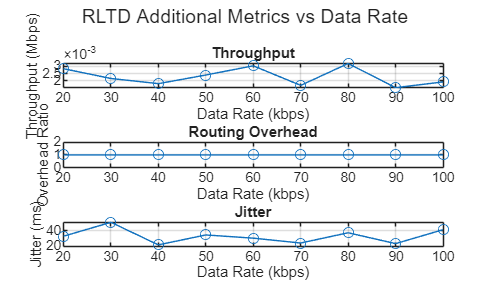


%% VISUALIZATION: ADDITIONAL METRICS VS DATA RATE
figure;
subplot(3,1,1);
plot(dataRates, metrics(:,5), '-o');
title('Throughput');
xlabel('Data Rate (kbps)');
ylabel('Throughput (Mbps)');
grid on;

subplot(3,1,2);
plot(dataRates, metrics(:,6), '-o');
title('Routing Overhead');
xlabel('Data Rate (kbps)');
ylabel('Overhead Ratio');
grid on;

subplot(3,1,3);
plot(dataRates, metrics(:,7), '-o');
title('Jitter');
xlabel('Data Rate (kbps)');
ylabel('Jitter (ms)');
grid on;

sgtitle('RLTD Additional Metrics vs Data Rate');

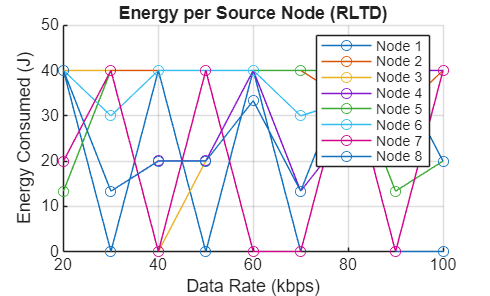


%% PLOT: ENERGY PER SOURCE NODE ACROSS DATA RATE
figure;
hold on;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]);
end
xlabel('Data Rate (kbps)');
ylabel('Energy Consumed (J)');
title('Energy per Source Node (RLTD)');
grid on;
legend show;
hold off;